Clustering test on data

First Technique : Random Cluster Start

Section one : Load data

clear all; close all;
rawData = load('Data.mat');
X = rawData.data.X;
Y = rawData.data.Y;
%randomize data set
Idx = randperm(length(X));
X = X(Idx,:,:);
Y = Y(Idx,:);

Section two visual data based on mean of first two dimensions

%Find the mean of first two color maps  
randomPortion =  randi(ceil(length(X)/40))

randomPortion = 25

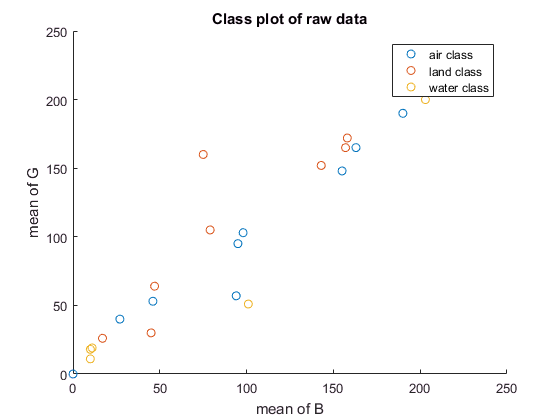

% mean_X = mean(X(1:randomPortion,randomPortion,2),2);
% mean_Y = mean(X(1:randomPortion,randomPortion,3),2);
mean_Y = X(1:randomPortion,end,2);
mean_X = X(1:randomPortion,end,3);
%Plot means of each example in their class colour
figure();
hold on;
for class = 1:3
    plot(mean_X(Y(1:randomPortion)==class),mean_Y(Y(1:randomPortion)==class),'o','MarkerSize',6,'MarkerFaceColor','none')
end
title('Class plot of raw data')
ylabel('mean of G')
xlabel('mean of B')
legend('air class','land class','water class')

Now we have the raw data ready , lets find some cluster nodes to start off the alogrithm

First we are going to spilt our images into only red , green and blue to find seperate centroids in our X array

% pass all the exmaples into the InitCentroids to find the starting centroids
numberOfClusters = 3; % only three classes present in this set
redX = X(:,:,1);
greenX = X(:,:,2);
blueX = X(:,:,3);

[ redCentroids ] = InitCentroids( redX , numberOfClusters )

The max distance to the 2 cluster is 8163.1427 
The max distance to the 3 cluster is 11009.9105 


redCentroids =    228   195   191   182   164   146   134   106    81    60    54    53    51    48    50    50    48    45    50    59    63    63    64   111   164   190   205   186   177   142   127   127   153   215   209   194   198   216   209   197   199   181   195   208   224   232   233   232   234   234
   255   255   255   254   254   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
     5     4     3     4     4     4     3     4     5     5     7     6     5     4     4     3     2     2     1     1     1     2     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


[ greenCentroids ] = InitCentroids( greenX , numberOfClusters )

The max distance to the 2 cluster is 9315.2852 
The max distance to the 3 cluster is 10152.4148 


greenCentroids =    232   234   238   241   242   242   241   242   245   246   248   248   249   250   251   251   252   252   252   252   253   254   253   253   254   254   255   255   255   255   255   255   255   254   254   254   254   254   254   254   254   254   254   254   253   252   251   250   251   252
     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     5     6     6     4    21    76     9     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   254   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255


[ blueCentroids ] = InitCentroids( blueX , numberOfClusters )

The max distance to the 2 cluster is 8261.4580 
The max distance to the 3 cluster is 11755.9988 


blueCentroids =    191   190   189   189   189   189   190   190   189   190   190   190   190   189   188   188   187   187   187   186   189   194   191   193   194   193   191   191   186   182   183   182   181   179   178   179   178   177   176   178   179   179   182   181   179   179   181   180   181   185
     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     5    13    15     6     5    15    29    30    29    26    23    20    19    16    15    13    11    10    10     5     2     3
   252   252   252   252   252   252   252   252   252   253   253   253   253   253   253   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   254   251   239   252   255   254   255   254   254   254   254   254   254   254   254


Now lets try to assign our data with each of these clusters and see how it performs just using these random data points.

[ redAssignment ] = AssignToClosest( redX ,  redCentroids );
%for each orginal class , find it corsponding index and class and compare it

for class = 1:3
    %find original class index
   class_idx = find(Y==class);
   % find corsponding assignments
   classBelongs = (redAssignment(class_idx));
   %find the unique assignments in that portion 
   values = unique(classBelongs)
   %find how many assignments were in a single class
   for i = 1:length(values)
       numberOfAssignments(i) = length( classBelongs(classBelongs == values(i)) );
   end
   highestAssignments(class) = max(numberOfAssignments)
end

values =      1
     2
     3


highestAssignments = 571

values =      1
     2
     3


highestAssignments =    571   617


values =      1
     2
     3


highestAssignments =    571   617   467


   RedErrorClass = 1 - sum(highestAssignments)/length(Y)

RedErrorClass = 0.4179

[ greenAssignment ] = AssignToClosest( greenX ,  greenCentroids );
for class = 1:3
    %find original class index
   class_idx = find(Y==class);
   % find corsponding assignments
   classBelongs = (greenAssignment(class_idx));
   %find the unique assignments in that portion 
   values = unique(classBelongs)
   %find how many assignments were in a single class
   for i = 1:length(values)
       numberOfAssignments(i) = length( classBelongs(classBelongs == values(i)) );
   end
   highestAssignments(class) = max(numberOfAssignments)
end

values =      1
     2
     3


highestAssignments =    523   617   467


values =      1
     2
     3


highestAssignments =    523   496   467


values =      1
     2
     3


highestAssignments =    523   496   411


   greenErrorClass =  1 - sum(highestAssignments)/length(Y)

greenErrorClass = 0.4970

[ blueAssignment ] = AssignToClosest( blueX ,  blueCentroids );
for class = 1:3
    %find original class index
   class_idx = find(Y==class);
   % find corsponding assignments
   classBelongs = (blueAssignment(class_idx));
   %find the unique assignments in that portion 
   values = unique(classBelongs)
   %find how many assignments were in a single class
   for i = 1:length(values)
       numberOfAssignments(i) = length( classBelongs(classBelongs == values(i)) );
   end
   max(numberOfAssignments)
   highestAssignments(class) = max(numberOfAssignments)
end

values =      1
     2
     3


ans = 552

highestAssignments =    552   496   411


values =      1
     2
     3


ans = 624

highestAssignments =    552   624   411


values =      1
     2
     3


ans = 586

highestAssignments =    552   624   586


   blueErrorClass =  1 - sum(highestAssignments)/length(Y)

blueErrorClass = 0.3802

Now acrosss all colour ranges it can be seen that the images aren't getting group together based off their corsponding groups in the labels that we are given .

These previous errors are a bit bias as we dont check to make sure the classes are different for each group assignement and often the highest class in each cluster was 2 meaning that the alogrithm isnt even getting close to accurate groupings.

So now compute the mean of each cluster group now and set it as the centroid and repeat until we converge on a point. Hopefully this will make distinct groupings.

lets try ten iterations to see if we get a reduction of error.

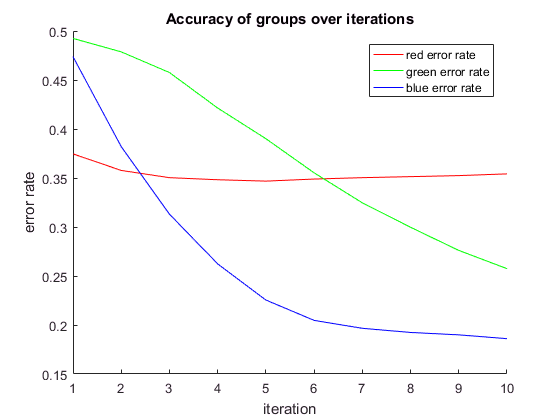

K = 10;
%step the centroids based off assignment
Error  = zeros(K,numberOfClusters);
for k = 1:K
    %compute the new centriods means
    for class = 1:numberOfClusters
       redCentroids(class,:) = mean(redX(redAssignment == class));
       greenCentroids(class,:) = mean(greenX(greenAssignment == class));
       blueCentroids(class,:) = mean(blueX(blueAssignment == class));
    end
    %compute new assignments
    [ redAssignment ] = AssignToClosest( redX ,  redCentroids );
    [ greenAssignment ] = AssignToClosest( greenX ,  greenCentroids );
    [ blueAssignment ] = AssignToClosest( blueX ,  blueCentroids );
    %check errors of current iteration of centroids
    [ Error(k,1) , redlabels] = ComputeError( redAssignment , Y );
    [ Error(k,2) , greenlabels ] = ComputeError( greenAssignment , Y );
    [ Error(k,3) , bluelabels ] = ComputeError( blueAssignment , Y );
end
%plot errors over iterations
figure();
hold on;
plot(1:K,Error(:,1),'r');
plot(1:K,Error(:,2),'g');
plot(1:K,Error(:,3),'b');
legend('red error rate','green error rate','blue error rate');
title('Accuracy of groups over iterations');
xlabel('iteration')
ylabel('error rate')

Lets compare the results of each centroid in each setup of RGB centriods by returning the examples back to images to see what has been grouped with what.

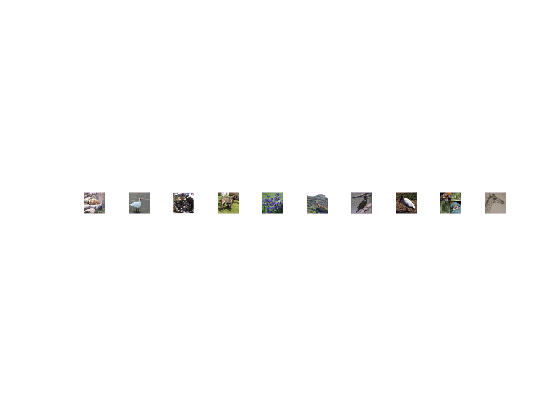

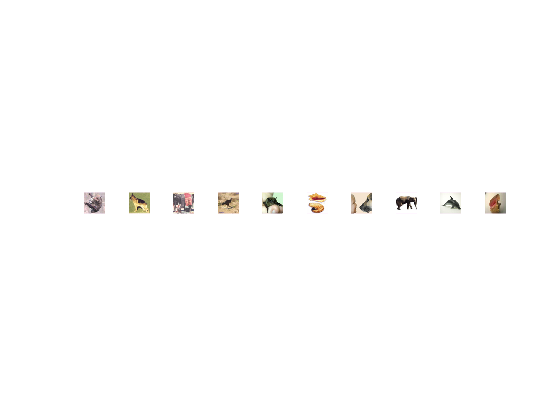

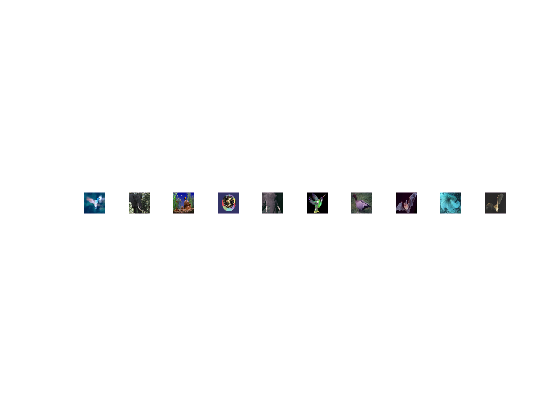

for class = 1 : numberOfClusters   
    figure();
    hold on;
    subplot(1,10,1);
    idx = find(redAssignment==class);
    count = 1;
    for i = 1:10
    remakeImage = uint8(reshape(X(idx(i),:,:),[50 50 3]));
    subplot(1,10,count);
    imshow(remakeImage)
    count = count + 1; 
    end
    hold off;
end